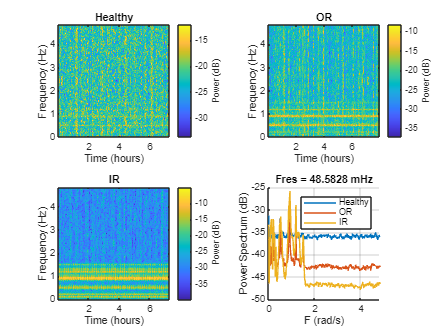

addpath('D:\bearing_dpl\padeborn_dataset\Paderborn Bearings');
addpath(genpath('D:\bearing_dpl\padeborn_dataset\Paderborn Bearings'));

Healthy = 'N09_M07_F10_K001';
OR = 'N09_M07_F10_KA01';
IR = 'N09_M07_F10_KI07';

bearingTypes = {Healthy, IR, OR};

% typeIdx = 1;
fileIdx = 2;

fs = 64e+3./2100./pi;

params.Tau = 2100.00;
params.TauR = 1500.00;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 10.00;
params.b = 3;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Initial conditions
initCon = [0.0; 0.0];

soma = Dendrite(0, paramsSoma, initCon);                     
dendrite = Dendrite(0, params, initCon);                     

% dendritic tree model                                       
tree = DendriteTreeModel();                          

% Add soma                                                   
tree.addDendrite(soma);    

figure
tiledlayout(2, 2)

for typeIdx = 1:3
    name = sprintf('%s_%d.mat', bearingTypes{typeIdx}, fileIdx);
    var_name = sprintf('%s_%d', bearingTypes{typeIdx}, fileIdx);
    load(name);

    sig = eval([var_name '.Y(7).Data']);
    sig = sig./rms(sig);
    nexttile
    pspectrum(sig, fs, "spectrogram");
    switch typeIdx
        case 1
            title('Healthy');
        case 2
            title('OR');
        case 3
            title('IR');
    end
    clear(var_name);
end

nexttile
for typeIdx = 1:3
    name = sprintf('%s_%d.mat', bearingTypes{typeIdx}, fileIdx);
    var_name = sprintf('%s_%d', bearingTypes{typeIdx}, fileIdx);
    load(name);

    sig = eval([var_name '.Y(7).Data']);
    
    hold on
    pspectrum(sig, fs, "power");
    xlabel('F (rad/s)')
    legend("Healthy", "OR", "IR");

    clear(var_name);
end

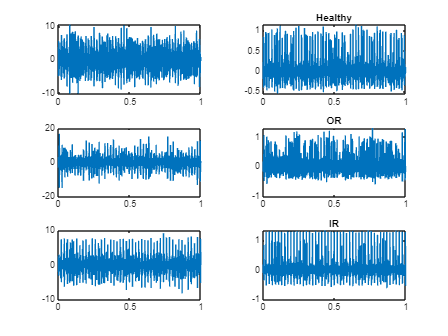

RAW


ans = 1.8624

NEURON


ans = 0.8743

RAW


ans = 2.0534

NEURON


ans = 1.0831

RAW


ans = 1.5332

NEURON


ans = 0.8547


figure
tiledlayout(3, 2)
for typeIdx = 1:3
    name = sprintf('%s_%d.mat', bearingTypes{typeIdx}, fileIdx);
    var_name = sprintf('%s_%d', bearingTypes{typeIdx}, fileIdx);
    load(name);

    sig = eval([var_name '.Y(7).Data']);
    t = eval([var_name '.X(2).Data']);
    sig = sig./rms(sig);
    sig = sig(1:64e+3+1);
    disp('RAW')
    approximateEntropy(resample( sig(1:64e+3++1), 1, 4 ))
    tree.addStimuli(0, sig);
    [t, sol] = treeSolver(tree, 1, 1/64e+3);
    disp('NEURON')
    approximateEntropy(resample( sol(1, 1:+64e+3+1), 1, 4))

    nexttile
    plot(t, sig)
    nexttile
    plot(t, sol(1, :))
    switch typeIdx
        case 1
            title('Healthy');
        case 2
            title('OR');
        case 3
            title('IR');
    end
    clear(var_name);
end

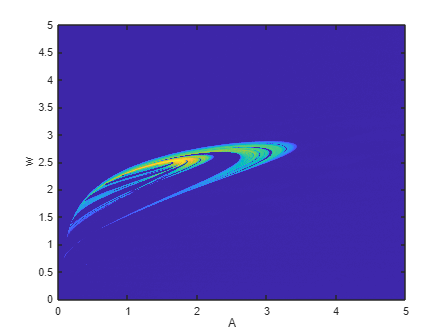

figure
imagesc(xdata, ydata, cdata)
set(gca, "YDir", "normal")
xlabel('A')
ylabel('w')